clc
clear all
close all

# Total energy balance PI tuning

m = 9;
%% Total energy balance
Ti = 1e-4;
Csm = 20e-3;		 % Average cluster capacitance
Nsm = 4;             % Submodules per cluster
L = 20e-3;           % Branch inductance
R = 0.001;	         % Branch resistance
% Input
Ax = 7000;
% Output
Ay = 5000;
Vxy_max = Ax+Ay;      % Branch voltage
Ix_max = 200;         % Input current
vc_ref = 1.5*Vxy_max; % Cluster capacitor voltage

PI

% Plant
k_teb = Ax/(6*Csm/Nsm*vc_ref)

k_teb = 12.9630

G_teb = k_teb*tf([1], [1, 0])


G_teb =
 
  12.96
  -----
    s
 
Continuous-time transfer function.
Model Properties



% Controller
xi = 1/sqrt(2);
wn = 100;
kc = 2*xi*wn/k_teb

kc = 10.9096

tau = 2*xi/wn

tau = 0.0141

C_teb = kc*tf([tau, 1], [tau, 0])


C_teb =
 
  0.1543 s + 10.91
  ----------------
     0.01414 s
 
Continuous-time transfer function.
Model Properties







% Parameters
Kp_teb = 6.48156886919677*3;
Ki_teb = 397.264633627808/20;
n_teb = 1-Ti*0.5*Ki_teb/Kp_teb;
% Initialization
[a_teb, u_teb] = deal(0);
vc0 = vc_ref*ones(m, 1);
Ec0 = (Csm/2)*vc0.^2;

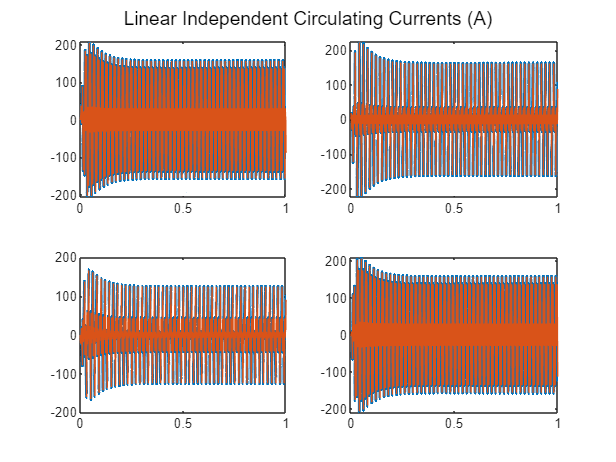

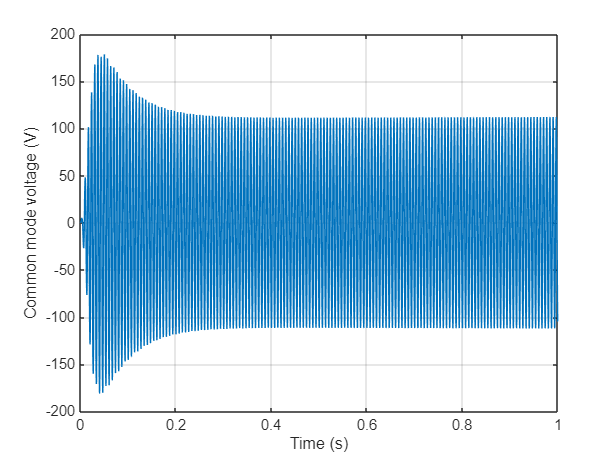

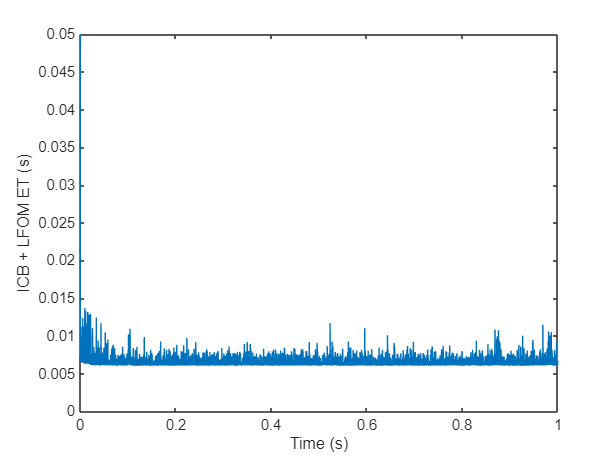

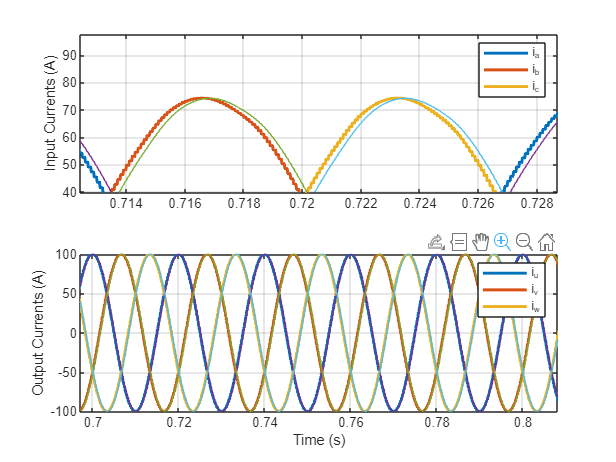

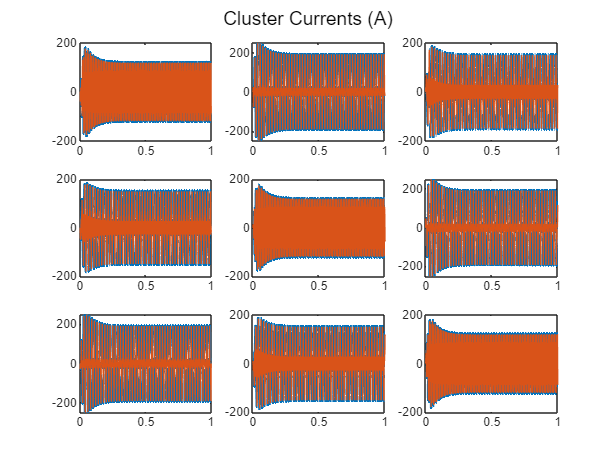

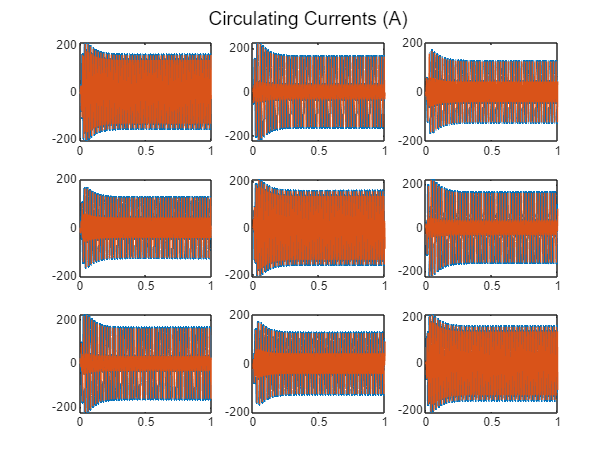

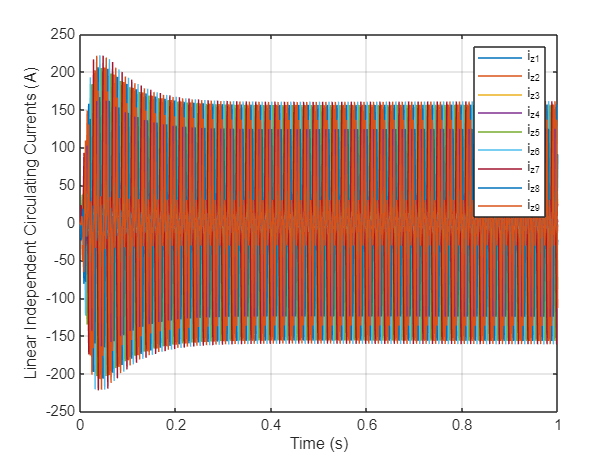

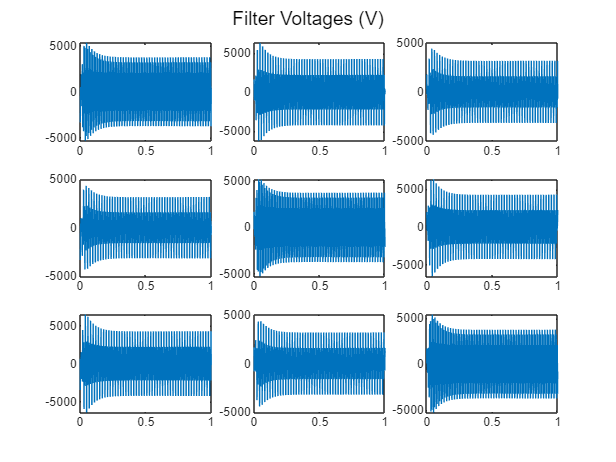

% TEB PI
% e_teb = (vc_ref-sqrt(4*2/C*abs(mean(Ec(:, t))))*sign(mean(Ec(:, t))));
e_teb = (vc_ref-sqrt(2/Csm*abs(mean(Ec(:, t))))*sign(mean(Ec(:, t))));
a_teb = (n_teb-1)*u_teb/Kp_teb+a_teb*n_teb;
u_teb = (e_teb-a_teb)*Kp_teb;
u_teb = clip(u_teb, -Ix_max, Ix_max); % Saturation between Ix_max*[-1, 1]

Ixd_ref(t) = u_teb;
ixa_ref(t) = Ixd_ref(t)*cos(gx(t))        - Ixq_ref(t)*sin(gx(t));
ixb_ref(t) = Ixd_ref(t)*cos(gx(t)-2*pi/3) - Ixq_ref(t)*sin(gx(t)-2*pi/3);
ixc_ref(t) = Ixd_ref(t)*cos(gx(t)+2*pi/3) - Ixq_ref(t)*sin(gx(t)+2*pi/3);